Prepared by

*Asif Newaz*

*Lecturer, EEE, IUT *

**Loading Images**

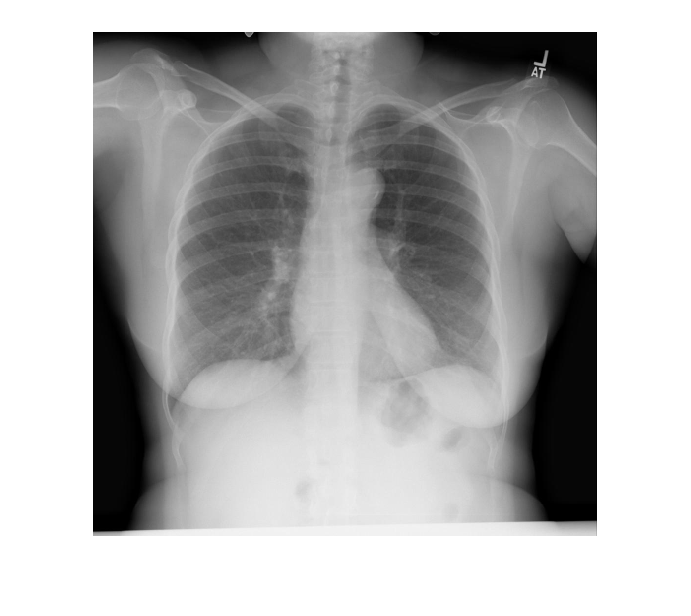

i= imread("CXR2664_IM-1145-1001.png");
ig= rgb2gray(i);
imshow(ig)

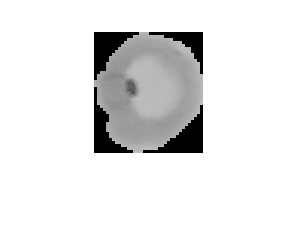

cell= imread('cell.png');
cell= rgb2gray(cell);
imshow(cell)

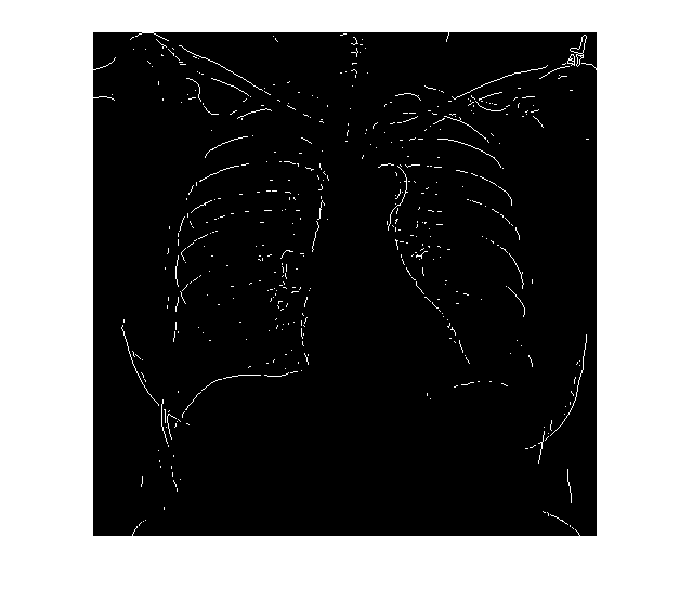

e1= edge (ig,'sobel');
imshow(e1)

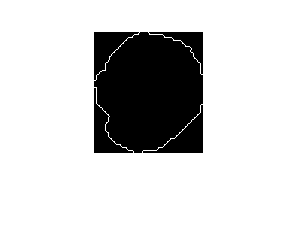

e2 = edge(cell, "sobel");
imshow(e2)

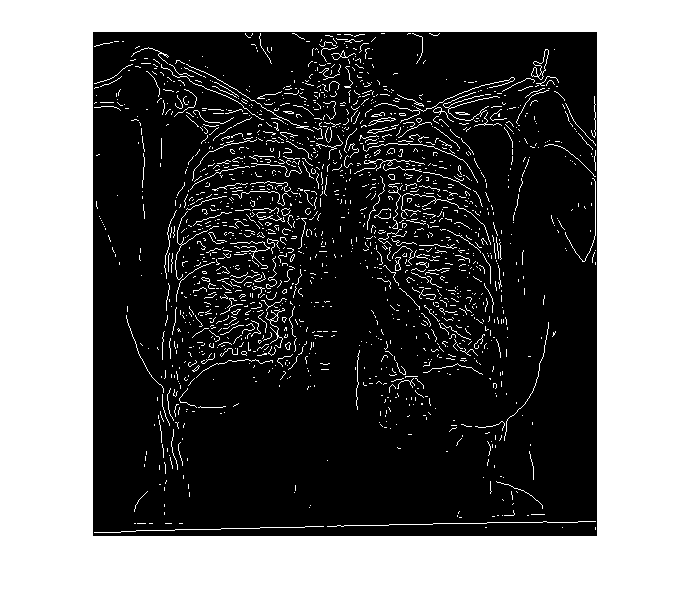

e11= edge (ig,'log');
imshow(e11)

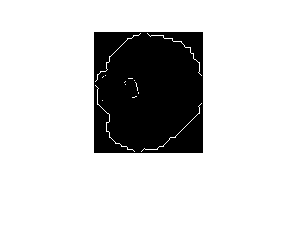

e22 = edge(cell, "log");
imshow(e22)

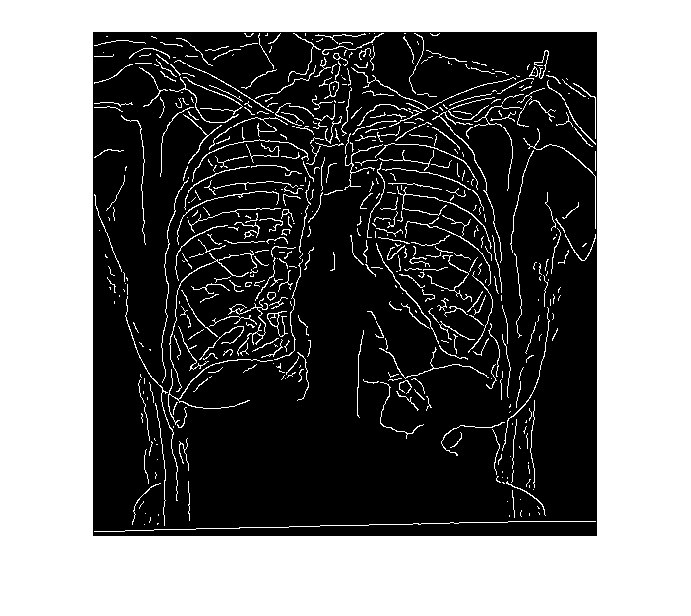

e111= edge(ig, "canny");
imshow(e111)

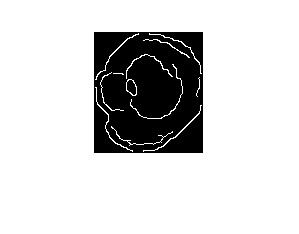

e222 = edge(cell, "canny");
imshow(e222)

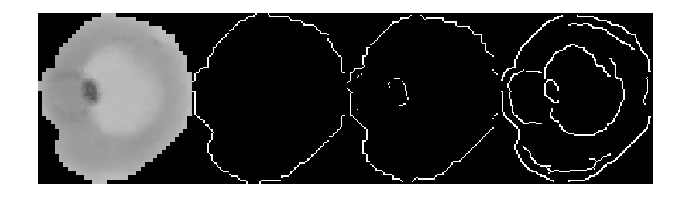

montage({cell, e2, e22, e222}, 'Size', [1,4])

**Defining threshold**

[l1, th22] = edge(cell, "log");
th22

th22 = 0.0052

imshow(l1)

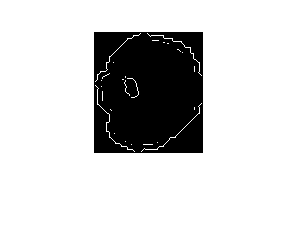

l2 = edge(cell, "log", 0.003); % check other threshold values
imshow(l2)

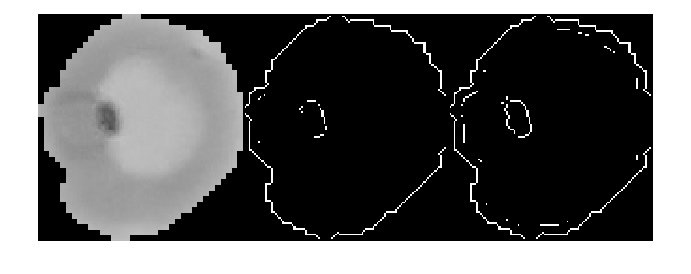

montage({cell, l1, l2}, 'Size', [1,3])

[e33, th33] = edge(cell, "canny");
th33

th33 =     0.0250    0.0625


imshow(e33)